clc;
clear;
close all;
fc= 915*1e6;  % Set USRP radio center frequency

fs = 1e7;
Ts = 1/fs;
Nfft = 64;
Ncp = 16;
indexOffset = @(m) mod(m + Nfft/2, Nfft) + 1;
preZero = 100;
postZero = 100;
subcarriers = (-Nfft/2):(Nfft/2-1);
pilotIndices = [ -21, -7, 7, 21 ];
allCarriers   = [-26:-1 1:26];
dataIndices   = setdiff(allCarriers, pilotIndices);

## **PART 1**

(1)    Generate a frame with STS, LTS, and 5 OFDM symbols using 4-QAM modulation for the data tones. Pre-pad and post-pad the frame with 100 zeros (100 zeros, STS, LTS, 5 OFDM symbols, 100 zeros). Plot the generated frame in the time domain with the correct time unit in  microseconds. Please mark the STS, LTS, and data symbols. Notice that the sampling rate of  the USRP is 10 MHz, which is different from the sampling rate of 20 MHz in Lab 3, and thus the frame duration is different. 

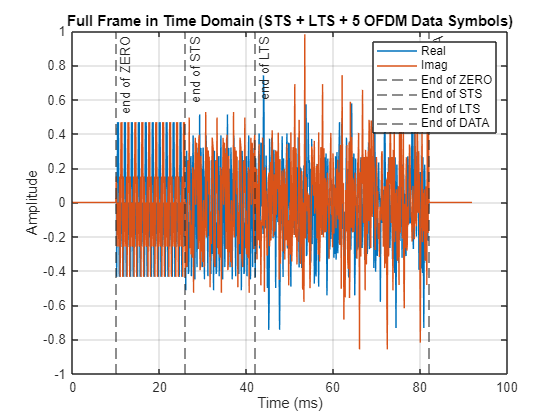

ltsFreq = zeros(1, Nfft);         % 64 subcarriers in total
stsFreq = zeros(1, Nfft); 
lts = [1 1 -1 -1 1 1 -1 1 -1 1 1 1 1 1 1 -1 -1 1 1 -1 1 -1 1 1 1 1 1 -1 -1 1 1 -1 1 -1 1 -1 -1 -1 -1 -1 1 1 -1 -1 1 -1 1 -1 1 1 1 1];
sts = [0 0 1+1i 0 0 0 -1-1i 0 0 0 1+1i 0 0 0 -1-1i 0 0 0 -1-1i 0 0 0 1+1i 0 0 0 0 0 0 -1-1i 0 0 0 -1-1i 0 0 0 1+1i 0 0 0 1+1i 0 0 0 1+1i 0 0 0 1+1i 0 0] * sqrt(13/6);

idx = 1;
for sc = allCarriers
    ltsFreq(sc + Nfft/2 + 1) = lts(idx);
    stsFreq(sc + Nfft/2 + 1) = sts(idx);
    idx = idx + 1;
end

stsTime = ifft(ifftshift(stsFreq)) * sqrt(Nfft);
STS = repmat(stsTime(1:16), 1, 10);

ltsTime = ifft(ifftshift(ltsFreq)) * sqrt(Nfft);
lts_cp = ltsTime(end-32+1:end);
LTS = [lts_cp ltsTime ltsTime];

M = 4;
numSym = 5;
dataFrame = zeros(numSym, 80);     % collect the time-domain signals (w/ CP) across all symbols
numPilotCarriers = 4;
numDataCarriers = 48;

DATA=[];
data_idx = [-26:-22, -20:-8, -6:-1, 1:6, 8:20, 22:26] + Nfft/2 + 1;
pilot_idx = [-21 -7 7 21] + Nfft/2 + 1;

data_bits_all = [];
for s = 1:numSym
    % new random bits
    data_bits = randi([0 3], numDataCarriers, 1);
    data_bits_all = [data_bits_all; data_bits];
    pilot_bits = randi([0 1], numPilotCarriers, 1) * 2 - 1;
    data_sym = qammod(data_bits, 4, 'UnitAveragePower', true);
    pilot_sym = pilot_bits;

    X = zeros(Nfft, 1);
    X(data_idx) = data_sym;
    X(pilot_idx) = pilot_sym;





    % build freq-domain vector
    x = ifft(ifftshift(X))* sqrt(Nfft);
    x_cp = [x(end - Ncp + 1:end); x];
    % ifft
    DATA = [DATA; x_cp]; % row for each symbol
end

DATA = DATA(:).';
ZERO = zeros(1,100);
fullFrame = [ZERO, STS, LTS, DATA, ZERO];
fullFrame = fullFrame/abs(max(fullFrame));

timeAxis = (0:length(fullFrame)-1) * Ts * 1e6;  % from 0 to (160-1)*Ts, in µs
figure;
plot(timeAxis, real(fullFrame), timeAxis, imag(fullFrame));
hold on;

xlabel('Time (ms)'); 
ylabel('Amplitude');
title('Full Frame in Time Domain (STS + LTS + 5 OFDM Data Symbols)');
zerolen = length(ZERO) * Ts * 1e6;
stsLen  = length(STS) * Ts * 1e6;
ltsLen  = length(LTS) * Ts * 1e6;
dataLen = length(DATA) * Ts * 1e6;
xline(zerolen, '--', 'end of ZERO');
xline(zerolen + stsLen, '--', 'end of STS');
xline(zerolen + stsLen + ltsLen, '--', 'end of LTS');
xline(zerolen + stsLen + ltsLen + dataLen, '--', 'end of DATA');
legend('Real','Imag', 'End of ZERO', 'End of STS', 'End of LTS', 'End of DATA'); 
grid on;
hold off;

(2)    Transmit the frame generated in (1). Plot the received frame in the time domain with the  correct time unit in microseconds. As in (1), please mark the STS, LTS, and data symbols.  Please make sure the received signal is of proper signal strength – it should not show signs of  clipping, and the signal can be easily distinguishable from the zeros.

info = findsdru();

Checking radio connections...


while info.Status ~= "Success"
    release(radio_Tx);
    release(radio_Rx);
    pause(1);
    info = findsdru();
end

l      = length(fullFrame);   % 一個 frame 長度
rx_l   = l;                   % 接收長度與傳送相同
[radio_Tx, radio_Rx] = USRP_init(rx_l);

USRP_init is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\Ricky\Desktop\CHAOGEGON_COMMLAB45\USRP_Sample_code

Change the MATLAB current folder or add its folder to the MATLAB path.

sr          = 1e7;   % 取樣頻率 (Hz)
maxRetries  = 20;    % 避免無限迴圈的保險值
attempt     = 1;
successFlag = false; % Tx+Rx 是否都成功
data = fullFrame.';
thrMag = 0.01;
match_filter = fliplr(conj(STS(1:Ncp)));

[radio_Tx, radio_Rx] = USRP_init(rx_l);
%%%%%%%%%%%%%%%%%%%%%%%%
buffer = zeros(1,length(data));

tunderrun = 0;
toverflow = 0;
maxattempts = 50;
success = 0;
match_filter = fliplr(conj(STS(1:Ncp)));
match_filter_LTS = fliplr(conj(LTS(33:96)));
start_point = 0;
for attempt = 1:maxattempts
    tunderrun = radio_Tx(data);
    [received_signal, ~, toverflow] = step(radio_Rx);
    corr = abs(conv(received_signal, match_filter, 'same'));
    corr_LTS = abs(conv(received_signal,match_filter_LTS, 'same'));
    maxval = max(corr);
    if  maxval >= 0.01;
        buffer(1,:) = received_signal.';
        [received_signal, ~, toverflow] = step(radio_Rx);
        buffer(2,:) = received_signal.';
        success = 1;
        break
    else
        fprintf("max corr = %d\n", max(corr));
    end
end
if success
    disp("SUCCESS!");
else
    release(radio_Tx);
    release(radio_Rx);
    disp("FAIL!");
end

reshape_buffer = reshape(buffer.',1,[]).';

% Release USRP resources
release(radio_Tx);
release(radio_Rx);
figure;
t = (0:length(reshape_buffer)-1) * (1e6/fs); % Convert to microseconds
plot(t, real(reshape_buffer), 'b');

hold on;
plot(t, imag(reshape_buffer), 'r');
legend("real","imag");
title('(2) Only buffer Received Frame (STS, LTS, OFDM Data)'); 
xlabel('Time (\mu s)'); 
ylabel('Amplitude'); 
grid on;

(3)    Apply the frame synchronization algorithm you designed in Lab 3 to identify the correct  beginning of the OFDM symbols. Please plot the match filter result.

for i = 1:length(reshape_buffer)-1
    if(corr(i) > 1.9)
        start_point = i-8+1;
        break
    end
end

figure;
t = (0:length(corr)-1) * (1e6/fs); % Convert to microseconds
stem(t, real(corr), 'b'); 

hold on;
stem(t, imag(corr), 'r');
title('(3) convolution with match filter(STS)'); 
xlabel('Time (\mu s)');
ylabel('Amplitude');
xline(start_point * (1e6/fs));
legend("real","imag", "start of STS")
grid on;
savefig(sprintf("heheheha"));
saveas(gcf,sprintf("heheheha.png"));

% 
% figure;
% t_lts = (0:length(corr_LTS)-1) * (1e6/fs); % Convert to microseconds
% stem(t, real(corr_LTS), 'b'); 
% hold on;
% stem(t, imag(corr_LTS), 'r');
% title('(2) Only buffer Received Frame (STS, LTS, OFDM Data)'); 
% xlabel('Time (\mu s)');
% ylabel('Amplitude');
% xline(start_point * (1e6/fs));
% grid on;
% savefig(sprintf("heheheha"));
% saveas(gcf,sprintf("heheheha.png"));

(4)    Based on the result, what index marks the beginning of the first long training symbols?

% figure;
% t = (0:length(reshape_buffer)-1) * (1e6/fs); % Convert to microseconds
% plot(t, real(reshape_buffer), 'b'); 
% hold on;
% plot(t, imag(reshape_buffer), 'r');
% title('(2) Only buffer Received Frame (STS, LTS, OFDM Data)'); 
% xlabel('Time (\mu s)');
% ylabel('Amplitude');
% xline(start_point*1e6/fs);
fprintf("start of LTS: %d", start_point + length(STS));
% grid on;
% savefig(sprintf("heheheheha"));
% saveas(gcf,sprintf("heheheheha.png"));

(5)    Transform the first long training symbol into the frequency domain and perform channel  estimation. Plot the magnitude and phase of the channel across the subcarriers, from subcarrier  index -26 to 26 (zero-subcarrier in the center).

rx_LTS = reshape_buffer(start_point+length(STS) : start_point+length(STS)+length(LTS)-1);


% corr_lts = conv(rx_LTS, match_filter_LTS, 'same');
% figure;
% t = (0:length(corr_lts)-1) * (1e6/fs); % Convert to microseconds
% plot(t, real(corr_lts), 'b'); 
% hold on;
% plot(t, imag(corr_lts), 'r');
% title('(2) Only buffer Received Frame (STS, LTS, OFDM Data)'); 
% xlabel('Time (\mu s)');
% ylabel('Amplitude');
% grid on;
% savefig(sprintf("heheheheha"));
% saveas(gcf,sprintf("heheheheha.png"));
% figure;
% t = (0:length(rx_LTS)-1) * (1e6/fs); % Convert to microseconds
% plot(t, real(rx_LTS), 'b'); 
% hold on;
% plot(t, imag(rx_LTS), 'r');
% title('(2) Only buffer Received Frame (STS, LTS, OFDM Data)'); 
% xlabel('Time (\mu s)');
% ylabel('Amplitude');
% grid on;
rx_second_lts = rx_LTS(end-Nfft+1:end);
rx_first_lts = rx_LTS(Nfft/2+1: Nfft/2+Nfft);
rx_lts_second = fftshift(fft(rx_second_lts)) / sqrt(Nfft);
rx_lts_first = fftshift(fft(rx_first_lts))/sqrt(Nfft);
H_est_first  = rx_lts_first .* ltsFreq.';  % element-wise division
figure;
plot(subcarriers, abs(H_est_first), '-r', 'DisplayName', 'First LTS');
xlabel('Subcarrier Index');
ylabel('Magnitude');
legend();
title('Channel Magnitude Response (First LTS)');
grid on;
figure;
stem(subcarriers, angle(H_est_first), '-r', 'DisplayName', 'First LTS');
xlabel('Subcarrier Index');
ylabel('Phase (radians)');
legend();
title('Channel Phase Response (First LTS)');
grid on;
% figure;
% plot(subcarriers, abs(rx_lts_second));

%fuck we send wrong LTS from OFDM, this wrong is propogated by HW3

(6)    Similar to (5), perform channel estimation using the second long training symbol. Plot the  magnitude and phase of the channel across the subcarriers, from subcarrier index -26 to 26  (zero-subcarrier in the center). For comparison, plot the results using the first long training  symbol on the same figure with a clear legend.


H_est_second = rx_lts_second .* ltsFreq.';

figure;
plot(subcarriers, abs(H_est_first), '-r', 'DisplayName', 'First LTS');
hold on;
plot(subcarriers, abs(H_est_second), '-b', 'DisplayName', 'Second LTS');
xlabel('Subcarrier Index');
ylabel('Magnitude');
legend();
title('Channel Magnitude Response (First LTS vs Second LTS)');
grid on;

figure;
stem(subcarriers, angle(H_est_first), '-r', 'DisplayName', 'First LTS');
hold on;
stem(subcarriers, angle(H_est_second), '-b', 'DisplayName', 'Second LTS');
xlabel('Subcarrier Index');
ylabel('Phase (radians)');
legend();
title('Channel Phase Response (First LTS vs Second LTS)');
grid on;


(7)    What frequencies do subcarriers -26, 0, and 26 correspond in this USRP transmission? 

fprintf("The frequencies of -26 , 0 , 26 are %f, %f, %f respectively", fc+fs/2*(-26/32), fc+0, fc+fs/2*26/32);

(8)    Find the samples corresponding to the OFDM symbols. Before equalization, plot the received  constellation for data tones. What do you observe? 

start_of_data = start_point + length(STS) + length(LTS);
data_block = reshape_buffer(start_of_data : start_of_data+length(DATA)-1);
% data_block = transpose(DATA);
all_rx_data = [];
all_rx = [];
data_idx = [-26:-22, -20:-8, -6:-1, 1:6, 8:20, 22:26] + Nfft/2 + 1;
numSym = 5;
for i = 1:numSym
    % Receiver side
    symbol_rx = data_block((i-1)*(Nfft+Ncp)+1 : i*(Nfft+Ncp));
    symbol_rx = symbol_rx(Ncp+1:end);  % Remove CP
    Y = fftshift(fft(symbol_rx)) / sqrt(Nfft);
    rx_data = Y(data_idx);
    all_rx_data = [all_rx_data; rx_data];
    all_rx = [all_rx; Y];
end
figure;
grid on;
plot(real(all_rx_data), imag(all_rx_data),'.');
title("constellation of received symbol");
xlabel("In-phase");
ylabel("Quadrature");

The received symbols are rotated round. Which is due to the CFO phenomenon.

(9)    We skip the carrier frequency offset estimation and correction since we use the same USRP for  transmission and reception in this experiment. Thus, without correcting carrier frequency  offset, equalize the OFDM symbols using the estimated channel in (5) and (6) in the frequency  domain. Plot the equalized received constellation for the data tones. Also, plot the transmitted  constellation in the same figure for comparison. What do you observe? 

H_five_times = repmat(H_est_second,numSym,1 );

equa_rx = all_rx./H_five_times;
equa_data = [];
for i =1:numSym
    equa_data_s = equa_rx((i-1)*Nfft+1: i*Nfft);
    equa_data = [equa_data; equa_data_s(data_idx)];
end
figure;
grid on;
plot(real(equa_data), imag(equa_data),'yx');
hold on;
plot(real(data_sym), imag(data_sym),'.', 'Color', "r");
title("constellation of received symbol with channel fix");
xlabel("In-phase");
ylabel("Quadrature");

We observe before we fix CFO, the constellation points were incorrect. However, after estimating the channel effect, the constallation points are almost on the right place.

% rx_dec = qamdemod(equa_data, 4, 'UnitAveragePower', true);
% tx_bits = de2bi(data_bits_all);
% data_sym_all = qammod(data_bits_all,4,'UnitAveragePower', true);
% rx_bits = de2bi(rx_dec);
% 
% % Reshape the bits to column vectors for comparison
% tx_bits = tx_bits(:);
% rx_bits = rx_bits(:);
% 
% % Compute the number of bit errors
% err_bits = sum(rx_bits ~= tx_bits);
% 
% % Compute the Bit Error Rate (BER)
% BER = err_bits / length(tx_bits);
% 
% % Display the result
% fprintf("BER = %f\n", BER);

(10)    Use the samples of the 5 OFDM symbols for signal strength calculation, and use the padded  zeros for noise calculation. What is the SNR of this received frame in dB? 

signal_pwr = mean(abs(data_block).^2);
start_of_zero = start_point + length(STS) + length(LTS) + length(DATA);
zero_block = reshape_buffer(start_of_zero : start_of_zero+length(ZERO)-1);
noise_pwr = mean(abs(zero_block).^2);
fprintf("SNR = %f dB", 10*log10(signal_pwr/noise_pwr));

(11)    Instead of transmitting only 5 OFDM symbols in each frame, increase to 100 OFDM symbols  per frame. Repeat frame transmission 100 times and calculate BER.

numSym = 100;
DATA=[];
data_bits_all = [];

for s = 1:numSym
    % new random bits
    data_bits = randi([0 3], numDataCarriers, 1);
    data_bits_all = [data_bits_all; data_bits];
    pilot_bits = randi([0 1], numPilotCarriers, 1) * 2 - 1;
    data_sym = qammod(data_bits, 4, 'UnitAveragePower', true);
    pilot_sym = pilot_bits;

    X = zeros(Nfft, 1);
    X(data_idx) = data_sym;
    X(pilot_idx) = pilot_sym;

    % build freq-domain vector
    x = ifft(ifftshift(X))* sqrt(Nfft);
    x_cp = [x(end - Ncp + 1:end); x];
    % ifft
    DATA = [DATA; x_cp]; % row for each symbol
  
end
DATA = DATA.';
ZERO = zeros(1,100);
fullFrame = [ZERO, STS, LTS, DATA, ZERO];
fullFrame = fullFrame/abs(max(fullFrame));
timeAxis = (0:length(fullFrame)-1) * Ts * 1e6;  % from 0 to (160-1)*Ts, in µs
% figure;
% plot(timeAxis, real(fullFrame), timeAxis, imag(fullFrame));
% hold on;
% 
% xlabel('Time (ms)'); 
% ylabel('Amplitude');
% title('Full Frame in Time Domain (STS + LTS + 5 OFDM Data Symbols)');
% zerolen = length(ZERO) * Ts * 1e6;
% stsLen  = length(STS) * Ts * 1e6;
% ltsLen  = length(LTS) * Ts * 1e6;
% dataLen = length(DATA) * Ts * 1e6;
% xline(zerolen, '--', 'end of ZERO');
% xline(zerolen + stsLen, '--', 'end of STS');
% xline(zerolen + stsLen + ltsLen, '--', 'end of LTS');
% xline(zerolen + stsLen + ltsLen + dataLen, '--', 'end of DATA');
% legend('Real','Imag', 'End of ZERO', 'End of STS', 'End of LTS', 'End of DATA'); 
% grid on;
% hold off;
info = findsdru();
while info.Status ~= "Success"
    release(radio_Tx);
    release(radio_Rx);
    pause(1);
    info = findsdru();
end

l      = length(fullFrame);   % 一個 frame 長度
rx_l   = l;                   % 接收長度與傳送相同
[radio_Tx, radio_Rx] = USRP_init(rx_l);
sr          = 1e7;   % 取樣頻率 (Hz)
maxRetries  = 20;    % 避免無限迴圈的保險值
attempt     = 1;
successFlag = false; % Tx+Rx 是否都成功
data = fullFrame.';
thrMag = 0.01;
match_filter = fliplr(conj(STS(1:Ncp)));

[radio_Tx, radio_Rx] = USRP_init(rx_l);
%%%%%%%%%%%%%%%%%%%%%%%%
num_repeats = 100;
BER_mean = 0;
tic;
for rep = 1:num_repeats
    buffer = zeros(1,length(data));
    
    tunderrun = 0;
    toverflow = 0;
    maxattempts = 50;
    success = 0;
    match_filter = fliplr(conj(STS(1:Ncp)));
    match_filter_LTS = fliplr(conj(LTS(33:96)));
    start_point = 0;
    for attempt = 1:maxattempts
        tunderrun = radio_Tx(data);
        [received_signal, ~, toverflow] = step(radio_Rx);
        corr = abs(conv(received_signal, match_filter, 'same'));
        corr_LTS = abs(conv(received_signal,match_filter_LTS, 'same'));
        maxval = max(corr);
        if  maxval >= 0.01;
            buffer(1,:) = received_signal.';
            [received_signal, ~, toverflow] = step(radio_Rx);
            buffer(2,:) = received_signal.';
            success = 1;
            break
        end
    end
    if success
        disp("SUCCESS!");
    else
        release(radio_Tx);
        release(radio_Rx);
        disp("FAIL!");
    end
    reshape_buffer = reshape(buffer.',1,[]).';
    for i = 1:length(reshape_buffer)-1
        if(corr(i) > 1.9)
            start_point = i-8+1;
            break
        end
    end
    
    rx_LTS = reshape_buffer(start_point+length(STS) : start_point+length(STS)+length(LTS)-1);
    rx_second_lts = rx_LTS(end-Nfft+1:end);
    rx_first_lts = rx_LTS(Nfft/2+1: Nfft/2+Nfft);
    rx_lts_second = fftshift(fft(rx_second_lts)) / sqrt(Nfft);
    rx_lts_first = fftshift(fft(rx_first_lts))/sqrt(Nfft);
    H_est_first  = rx_lts_first .* ltsFreq.';  % element-wise division
    H_est_second = rx_lts_second .* ltsFreq.';
    start_of_data = start_point + length(STS) + length(LTS);
    data_block = reshape_buffer(start_of_data : start_of_data+length(DATA)-1);
    all_rx_data = [];
    all_rx = [];
    data_idx = [-26:-22, -20:-8, -6:-1, 1:6, 8:20, 22:26] + Nfft/2 + 1;
    for i = 1:numSym
        % Receiver side
        symbol_rx = data_block((i-1)*(Nfft+Ncp)+1 : i*(Nfft+Ncp));
        symbol_rx = symbol_rx(Ncp+1:end);  % Remove CP
        Y = fftshift(fft(symbol_rx)) / sqrt(Nfft);
        rx_data = Y(data_idx);
        all_rx_data = [all_rx_data; rx_data];
        all_rx = [all_rx; Y];
    end
    
    H_100_times = repmat(H_est_second,numSym,1 );
    
    equa_rx = all_rx./H_100_times;
    equa_data = [];
    for i =1:numSym
        equa_data_s = equa_rx((i-1)*Nfft+1: i*Nfft);
        equa_data = [equa_data; equa_data_s(data_idx)];
    end
    rx_dec = qamdemod(equa_data, 4, 'UnitAveragePower', true);
    tx_bits = de2bi(data_bits_all, 2, 'left-msb');
    data_sym_all = qammod(data_bits_all,4,'UnitAveragePower', true);
    rx_bits = de2bi(rx_dec, 2, 'left-msb');
    
    % Reshape the bits to column vectors for comparison
    tx_bits = tx_bits(:);
    rx_bits = rx_bits(:);
    
    % Compute the number of bit errors
    err_bits = sum(rx_bits ~= tx_bits);
    
    % Compute the Bit Error Rate (BER)
    BER = err_bits / length(tx_bits);
    BER_mean = BER_mean + BER;
end
elapsedTime = toc; % 結束計時並獲取經過的時間


fprintf('BER = %f', BER_mean/num_repeats);

% Release USRP resources
release(radio_Tx);
release(radio_Rx);

(12)    Following (11), how many bits are transmitted to obtain one BER value? As a side note, many  wireless experiments aim for a BER level in the order of 10^-9 . If we want to reach a BER  precision in the order of 10 , how many times do you need to repeat the frame transmission?  How long does it take to perform the experiment in (11)? How much time is expected if we were to reach a BER precision in the order of 10^-9 ? 

100 frames * 100symbols * 48 data tones * 2bits = 960000 bits

10^9/960000= 1041.667* 100 frames to attain the desired precision

1041.667 * elapsedTime = 15125 second to perform this precision.

fprintf('Elapsed time we performed: %.2f seconds\n', elapsedTime);

(13)    Vary the transmit power digitally and calculate BER in each power setting as in (11). Plot BER  vs SNR in dB. Please explore a range of power so that you observe BER reduction with increasing transmit power. Also, increase the transmit power until clipping happens, which may  result in additional errors despite a large received signal strength. Please briefly describe your  figure. As a side note, a trick to vary the transmit power is to vary only the amplitude of the  OFDM symbols, not the STS and LTS. As a result, you will be able to detect the beginning of  the frame regardless of the power of the OFDM symbols. However, when using this method,  you need to remember the amplification factor between LTS and the OFDM symbols and scale  the estimated channel accordingly.

numSym = 100;
DATA=[];
data_bits_all = [];

for s = 1:numSym
    % new random bits
    data_bits = randi([0 3], numDataCarriers, 1);
    data_bits_all = [data_bits_all; data_bits];
    pilot_bits = randi([0 1], numPilotCarriers, 1) * 2 - 1;
    data_sym = qammod(data_bits, 4, 'UnitAveragePower', true);
    pilot_sym = pilot_bits;

    X = zeros(Nfft, 1);
    X(data_idx) = data_sym;
    X(pilot_idx) = pilot_sym;

    % build freq-domain vector
    x = ifft(ifftshift(X))* sqrt(Nfft);
    x_cp = [x(end - Ncp + 1:end); x];
    % ifft
    DATA = [DATA; x_cp]; % row for each symbol
  
end
DATA = DATA.';
ZERO = zeros(1,100);
fullFrame = [ZERO, STS, LTS, DATA, ZERO];
fullFrame = fullFrame/abs(max(fullFrame));
timeAxis = (0:length(fullFrame)-1) * Ts * 1e6;  % from 0 to (160-1)*Ts, in µs
% figure;
% plot(timeAxis, real(fullFrame), timeAxis, imag(fullFrame));
% hold on;
% 
% xlabel('Time (ms)'); 
% ylabel('Amplitude');
% title('Full Frame in Time Domain (STS + LTS + 5 OFDM Data Symbols)');
% zerolen = length(ZERO) * Ts * 1e6;
% stsLen  = length(STS) * Ts * 1e6;
% ltsLen  = length(LTS) * Ts * 1e6;
% dataLen = length(DATA) * Ts * 1e6;
% xline(zerolen, '--', 'end of ZERO');
% xline(zerolen + stsLen, '--', 'end of STS');
% xline(zerolen + stsLen + ltsLen, '--', 'end of LTS');
% xline(zerolen + stsLen + ltsLen + dataLen, '--', 'end of DATA');
% legend('Real','Imag', 'End of ZERO', 'End of STS', 'End of LTS', 'End of DATA'); 
% grid on;
% hold off;
info = findsdru();
while info.Status ~= "Success"
    release(radio_Tx);
    release(radio_Rx);
    pause(1);
    info = findsdru();
end

l      = length(fullFrame);   % 一個 frame 長度
rx_l   = l;                   % 接收長度與傳送相同
[radio_Tx, radio_Rx] = USRP_init(rx_l);
sr          = 1e7;   % 取樣頻率 (Hz)
maxRetries  = 20;    % 避免無限迴圈的保險值
attempt     = 1;
successFlag = false; % Tx+Rx 是否都成功
data = fullFrame.';
thrMag = 0.01;
match_filter = fliplr(conj(STS(1:Ncp)));

[radio_Tx, radio_Rx] = USRP_init(rx_l);
%%%%%%%%%%%%%%%%%%%%%%%%
num_repeats = 100;

tic;
Gain_range = (-9:3:9);
Gain_range = 10.^(Gain_range/10);
BER_plot = zeros(length(Gain_range),1);
SNR_plot = zeros(length(Gain_range),1);
for cnt = 1:length(Gain_range)
    BER_mean = 0;
    SNR_mean = 0;
    fullFrame = [ZERO, STS, LTS, DATA, ZERO];
    fullFrame = fullFrame/abs(max(fullFrame));
    fullFrame(421:8420) = fullFrame(421:8420) * Gain_range(cnt);
    data = fullFrame.';
    for rep = 1:num_repeats
        buffer = zeros(1,length(data));
        
        tunderrun = 0;
        toverflow = 0;
        maxattempts = 50;
        success = 0;
        match_filter = fliplr(conj(STS(1:Ncp)));
        match_filter_LTS = fliplr(conj(LTS(33:96)));
        start_point = 0;
        for attempt = 1:maxattempts
            tunderrun = radio_Tx(data);
            [received_signal, ~, toverflow] = step(radio_Rx);
            corr = abs(conv(received_signal, match_filter, 'same'));
            corr_LTS = abs(conv(received_signal,match_filter_LTS, 'same'));
            maxval = max(corr);
            if  maxval >= 0.01;
                buffer(1,:) = received_signal.';
                [received_signal, ~, toverflow] = step(radio_Rx);
                buffer(2,:) = received_signal.';
                success = 1;
                break
            end
        end
        if success
            disp("SUCCESS!");
        else
            release(radio_Tx);
            release(radio_Rx);
            disp("FAIL!");
        end
        reshape_buffer = reshape(buffer.',1,[]).';
        for i = 1:length(reshape_buffer)-1
            if(corr(i) > 1.9)
                start_point = i-8+1;
                break
            end
        end
        
        rx_LTS = reshape_buffer(start_point+length(STS) : start_point+length(STS)+length(LTS)-1);
        rx_second_lts = rx_LTS(end-Nfft+1:end);
        rx_first_lts = rx_LTS(Nfft/2+1: Nfft/2+Nfft);
        rx_lts_second = fftshift(fft(rx_second_lts)) / sqrt(Nfft);
        rx_lts_first = fftshift(fft(rx_first_lts))/sqrt(Nfft);
        H_est_first  = rx_lts_first .* ltsFreq.';  % element-wise division
        H_est_second = rx_lts_second .* ltsFreq.';
        start_of_data = start_point + length(STS) + length(LTS);
        data_block = reshape_buffer(start_of_data : start_of_data+length(DATA)-1);
        all_rx_data = [];
        all_rx = [];
        data_idx = [-26:-22, -20:-8, -6:-1, 1:6, 8:20, 22:26] + Nfft/2 + 1;
        for i = 1:numSym
            % Receiver side
            symbol_rx = data_block((i-1)*(Nfft+Ncp)+1 : i*(Nfft+Ncp));
            symbol_rx = symbol_rx(Ncp+1:end);  % Remove CP
            Y = fftshift(fft(symbol_rx)) / sqrt(Nfft);
            rx_data = Y(data_idx);
            all_rx_data = [all_rx_data; rx_data];
            all_rx = [all_rx; Y];
        end
        
        H_100_times = repmat(H_est_second,numSym,1 );
        
        equa_rx = all_rx./H_100_times;
        equa_data = [];
        for i =1:numSym
            equa_data_s = equa_rx((i-1)*Nfft+1: i*Nfft);
            equa_data = [equa_data; equa_data_s(data_idx)];
        end
        rx_dec = qamdemod(equa_data, 4, 'UnitAveragePower', true);
        tx_bits = de2bi(data_bits_all, 2, 'left-msb');
        data_sym_all = qammod(data_bits_all,4,'UnitAveragePower', true);
        rx_bits = de2bi(rx_dec, 2, 'left-msb');
        
        % Reshape the bits to column vectors for comparison
        tx_bits = tx_bits(:);
        rx_bits = rx_bits(:);
        
        % Compute the number of bit errors
        err_bits = sum(rx_bits ~= tx_bits);
        
        % Compute the Bit Error Rate (BER)
        BER = err_bits / length(tx_bits);
        BER_mean = BER_mean + BER;

        signal_pwr = mean(abs(data_block).^2);
        start_of_zero = start_point + length(STS) + length(LTS) + length(DATA);
        zero_block = reshape_buffer(start_of_zero : start_of_zero+length(ZERO)-1);
        noise_pwr = mean(abs(zero_block).^2);
        SNR_mean = SNR_mean + 10*log10(signal_pwr/noise_pwr);
    end
    BER_mean = BER_mean/num_repeats;
    SNR_mean = SNR_mean/num_repeats;
    BER_plot(cnt) = BER_mean;
    SNR_plot(cnt) = SNR_mean;
end
elapsedTime = toc; % 結束計時並獲取經過的時間


% Release USRP resources
release(radio_Tx);
release(radio_Rx);
figure;
plot(BER_plot, 'o');
xlabel("SNRINDEX");
ylabel("BER")
title("The BER for different SNR")

The graph is the BER for different SNR index. For the Gain increase from low to high (SNR increase) the clipping occurs, the BER increase.

% 
% Gain_range = (-9:3:9);
% Gain_range = 10.^(Gain_range/10);

figure;
plot(SNR_plot, BER_plot,'x')

The given plot is the BER for different SNR. The reason why we plot two graph is that when we transmit high SNR, it will decrease to low SNR for USRP real transmitting. We think the reason is that our USRP cannot transmit high power symobl thus decrease.

(14)    Repeat (13) for 16-QAM. Plot BER vs SNR in dB.

numSym = 100;
DATA_16QAM=[];
data_bits_all_16QAM = [];

for s = 1:numSym
    % new random bits
    data_bits = randi([0 15], numDataCarriers, 1);
    data_bits_all_16QAM = [data_bits_all_16QAM; data_bits];
    pilot_bits_16QAM = randi([0 1], numPilotCarriers, 1) * 2 - 1;
    data_sym_16QAM = qammod(data_bits, 16, 'UnitAveragePower', true);
    pilot_sym_16QAM = pilot_bits_16QAM;

    X_16QAM = zeros(Nfft, 1);
    X_16QAM(data_idx) = data_sym_16QAM;
    X_16QAM(pilot_idx) = pilot_sym_16QAM;

    % build freq-domain vector
    x_16QAM = ifft(ifftshift(X_16QAM))* sqrt(Nfft);
    x_cp_16QAM = [x_16QAM(end - Ncp + 1:end); x_16QAM];
    % ifft
    DATA_16QAM = [DATA_16QAM; x_cp_16QAM]; % row for each symbol
  
end
DATA_16QAM = DATA_16QAM.';
ZERO_16QAM = zeros(1,100);
fullFrame_16QAM = [ZERO_16QAM, STS, LTS, DATA_16QAM, ZERO_16QAM];
fullFrame_16QAM = fullFrame_16QAM/abs(max(fullFrame_16QAM));
timeAxis_16QAM = (0:length(fullFrame_16QAM)-1) * Ts * 1e6;  % from 0 to (160-1)*Ts, in µs
% figure;
% plot(timeAxis_16QAM, real(fullFrame_16QAM), timeAxis_16QAM, imag(fullFrame_16QAM));
% hold on;
% 
% xlabel('Time (ms)'); 
% ylabel('Amplitude');
% title('Full Frame in Time Domain (STS + LTS + 5 OFDM Data Symbols)');
% zerolen_16QAM = length(ZERO_16QAM) * Ts * 1e6;
% stsLen_16QAM  = length(STS) * Ts * 1e6;
% ltsLen_16QAM  = length(LTS) * Ts * 1e6;
% dataLen_16QAM = length(DATA_16QAM) * Ts * 1e6;
% xline(zerolen_16QAM, '--', 'end of ZERO');
% xline(zerolen_16QAM + stsLen_16QAM, '--', 'end of STS');
% xline(zerolen_16QAM + stsLen_16QAM + ltsLen_16QAM, '--', 'end of LTS');
% xline(zerolen_16QAM + stsLen_16QAM + ltsLen_16QAM + dataLen_16QAM, '--', 'end of DATA');
% legend('Real','Imag', 'End of ZERO', 'End of STS', 'End of LTS', 'End of DATA'); 
% grid on;
% hold off;
info = findsdru();
while info.Status ~= "Success"
    release(radio_Tx);
    release(radio_Rx);
    pause(1);
    info = findsdru();
end

l      = length(fullFrame_16QAM);   % 一個 frame 長度
rx_l   = l;                   % 接收長度與傳送相同
[radio_Tx, radio_Rx] = USRP_init(rx_l);
sr          = 1e7;   % 取樣頻率 (Hz)
maxRetries  = 20;    % 避免無限迴圈的保險值
attempt     = 1;
successFlag = false; % Tx+Rx 是否都成功
data_16QAM = fullFrame_16QAM.';
thrMag = 0.01;
match_filter = fliplr(conj(STS(1:Ncp)));

[radio_Tx, radio_Rx] = USRP_init(rx_l);
%%%%%%%%%%%%%%%%%%%%%%%%
num_repeats = 100;

tic;
Gain_range = (-9:3:9);
Gain_range = 10.^(Gain_range/10);
BER_plot_16QAM = zeros(length(Gain_range),1);
SNR_plot_16QAM = zeros(length(Gain_range),1);
for cnt = 1:length(Gain_range)
    BER_mean = 0;
    SNR_mean = 0;
    fullFrame_16QAM = [ZERO_16QAM, STS, LTS, DATA_16QAM, ZERO_16QAM];
    fullFrame_16QAM = fullFrame_16QAM/abs(max(fullFrame_16QAM));
    fullFrame_16QAM(421:8420) = fullFrame_16QAM(421:8420) * Gain_range(cnt);
    data_16QAM = fullFrame_16QAM.';
    for rep = 1:num_repeats
        buffer = zeros(1,length(data_16QAM));
        
        tunderrun = 0;
        toverflow = 0;
        maxattempts = 50;
        success = 0;
        match_filter = fliplr(conj(STS(1:Ncp)));
        match_filter_LTS = fliplr(conj(LTS(33:96)));
        start_point = 0;
        for attempt = 1:maxattempts
            tunderrun = radio_Tx(data_16QAM);
            [received_signal, ~, toverflow] = step(radio_Rx);
            corr = abs(conv(received_signal, match_filter, 'same'));
            corr_LTS = abs(conv(received_signal,match_filter_LTS, 'same'));
            maxval = max(corr);
            if  maxval >= 0.01;
                buffer(1,:) = received_signal.';
                [received_signal, ~, toverflow] = step(radio_Rx);
                buffer(2,:) = received_signal.';
                success = 1;
                break
            end
        end
        if success
            disp("SUCCESS!");
        else
            release(radio_Tx);
            release(radio_Rx);
            disp("FAIL!");
        end
        reshape_buffer = reshape(buffer.',1,[]).';
        for i = 1:length(reshape_buffer)-1
            if(corr(i) > 1.9)
                start_point = i-8+1;
                break
            end
        end
        
        rx_LTS = reshape_buffer(start_point+length(STS) : start_point+length(STS)+length(LTS)-1);
        rx_second_lts = rx_LTS(end-Nfft+1:end);
        rx_first_lts = rx_LTS(Nfft/2+1: Nfft/2+Nfft);
        rx_lts_second = fftshift(fft(rx_second_lts)) / sqrt(Nfft);
        rx_lts_first = fftshift(fft(rx_first_lts))/sqrt(Nfft);
        H_est_first  = rx_lts_first .* ltsFreq.';  % element-wise division
        H_est_second = rx_lts_second .* ltsFreq.';
        start_of_data = start_point + length(STS) + length(LTS);
        data_block = reshape_buffer(start_of_data : start_of_data+length(DATA_16QAM)-1);
        all_rx_data = [];
        all_rx = [];
        data_idx = [-26:-22, -20:-8, -6:-1, 1:6, 8:20, 22:26] + Nfft/2 + 1;
        for i = 1:numSym
            % Receiver side
            symbol_rx = data_block((i-1)*(Nfft+Ncp)+1 : i*(Nfft+Ncp));
            symbol_rx = symbol_rx(Ncp+1:end);  % Remove CP
            Y = fftshift(fft(symbol_rx)) / sqrt(Nfft);
            rx_data = Y(data_idx);
            all_rx_data = [all_rx_data; rx_data];
            all_rx = [all_rx; Y];
        end
        
        H_100_times = repmat(H_est_second,numSym,1 );
        
        equa_rx = all_rx./H_100_times;
        equa_data = [];
        for i =1:numSym
            equa_data_s = equa_rx((i-1)*Nfft+1: i*Nfft);
            equa_data = [equa_data; equa_data_s(data_idx)];
        end
        rx_dec = qamdemod(equa_data, 16, 'UnitAveragePower', true);
        tx_bits = de2bi(data_bits_all_16QAM, 4, 'left-msb');
        data_sym_all = qammod(data_bits_all_16QAM,16,'UnitAveragePower', true);
        rx_bits = de2bi(rx_dec, 4, 'left-msb');
        
        % Reshape the bits to column vectors for comparison
        tx_bits = tx_bits(:);
        rx_bits = rx_bits(:);
        
        % Compute the number of bit errors
        err_bits = sum(rx_bits ~= tx_bits);
        
        % Compute the Bit Error Rate (BER)
        BER = err_bits / length(tx_bits);
        BER_mean = BER_mean + BER;

        signal_pwr = mean(abs(data_block).^2);
        start_of_zero = start_point + length(STS) + length(LTS) + length(DATA_16QAM);
        zero_block = reshape_buffer(start_of_zero : start_of_zero+length(ZERO_16QAM)-1);
        noise_pwr = mean(abs(zero_block).^2);
        SNR_mean = SNR_mean + 10*log10(signal_pwr/noise_pwr);
    end
    BER_mean = BER_mean/num_repeats;
    SNR_mean = SNR_mean/num_repeats;
    BER_plot_16QAM(cnt) = BER_mean;
    SNR_plot_16QAM(cnt) = SNR_mean;
end
elapsedTime = toc; % 結束計時並獲取經過的時間

% Release USRP resources
release(radio_Tx);
release(radio_Rx);

figure;
plot(BER_plot_16QAM, '-');
xlabel("SNRINDEX");
ylabel("BER");
title("BER vs SNR for 16 QAM");

figure;
plot(SNR_plot_16QAM, BER_plot_16QAM,'r-'); hold on;
plot(SNR_plot, BER_plot,'b-'); hold off;
xlabel("SNR");
ylabel("BER");
legend("16QAM", "4QAM")
title("16QAM, 4QAM comparison for different SNR value")

(15)    Compare the results for 4-QAM in (13) with the results for 16-QAM in (14). What do you  observe?

The 16QAM will have a higher BER, this is quite obvious since the 16QAM is hard to defend of noise then 4 QAM under same upower. 

## **PART 2**

(1)    Add a 5 ppm artificial CFO to the transmitted frame (with 100 OFDM symbols). Transmit and  receive the frame using the same USRP. Estimate the channel using the two long training  symbols. Plot the magnitude and phase of the estimated channel for both estimates across the  subcarriers, from subcarrier index -26 to 26 (zero-subcarrier in the center). What do you  observe? 

numSym = 100;
DATA=[];
data_bits_all = [];
cfo_ppm = 5e-6;  % 5 ppm
cfo_freq_shift = cfo_ppm * 915*1e6;  % Frequency shift in Hz
pilot_all = [];
for s = 1:numSym
    % new random bits
    data_bits = randi([0 3], numDataCarriers, 1);
    data_bits_all = [data_bits_all; data_bits];
    pilot_bits = randi([0 1], numPilotCarriers, 1) * 2 - 1;
    data_sym = qammod(data_bits, 4, 'UnitAveragePower', true);
    pilot_sym = pilot_bits;

    X = zeros(Nfft, 1);
    X(data_idx) = data_sym;
    X(pilot_idx) = pilot_sym;
    pilot_all = [pilot_all; pilot_bits];
    % build freq-domain vector
    x = ifft(ifftshift(X))* sqrt(Nfft);
    x_cp = [x(end - Ncp + 1:end); x];
    % ifft
    DATA = [DATA; x_cp]; % row for each symbol
  
end
DATA = DATA.';
ZERO = zeros(1,100);
fullFrame = [ZERO, STS, LTS, DATA, ZERO];
% Add CFO by multiplying the signal with a complex exponential
cfo_factor = exp(1i * 2 * pi * cfo_freq_shift * (0:length(fullFrame)-1) * Ts);
fullFrame = fullFrame .* cfo_factor;
fullFrame = fullFrame/abs(max(fullFrame));
timeAxis = (0:length(fullFrame)-1) * Ts * 1e6;  % from 0 to (160-1)*Ts, in µs

info = findsdru();
while info.Status ~= "Success"
    release(radio_Tx);
    release(radio_Rx);
    pause(1);
    info = findsdru();
end

l      = length(fullFrame);   % 一個 frame 長度
rx_l   = l;                   % 接收長度與傳送相同
[radio_Tx, radio_Rx] = USRP_init(rx_l);
sr          = 1e7;   % 取樣頻率 (Hz)
maxRetries  = 20;    % 避免無限迴圈的保險值
attempt     = 1;
successFlag = false; % Tx+Rx 是否都成功
data = fullFrame.';
thrMag = 0.01;
match_filter = fliplr(conj(STS(1:Ncp)));

[radio_Tx, radio_Rx] = USRP_init(rx_l);
%%%%%%%%%%%%%%%%%%%%%%%%
num_repeats = 100;
BER_mean = 0;

for rep = 1:num_repeats
    buffer = zeros(1,length(data));
    
    tunderrun = 0;
    toverflow = 0;
    maxattempts = 50;
    success = 0;
    match_filter = fliplr(conj(STS(1:Ncp)));
    match_filter_LTS = fliplr(conj(LTS(33:96)));
    start_point = 0;
    for attempt = 1:maxattempts
        tunderrun = radio_Tx(data);
        [received_signal, ~, toverflow] = step(radio_Rx);
        corr = abs(conv(received_signal, match_filter, 'same'));
        corr_LTS = abs(conv(received_signal,match_filter_LTS, 'same'));
        maxval = max(corr);
        if  maxval >= 0.01;
            buffer(1,:) = received_signal.';
            [received_signal, ~, toverflow] = step(radio_Rx);
            buffer(2,:) = received_signal.';
            success = 1;
            break
        end
    end
    if success
        disp("SUCCESS!");
    else
        release(radio_Tx);
        release(radio_Rx);
        disp("FAIL!");
    end
    reshape_buffer = reshape(buffer.',1,[]).';
    for i = 1:length(reshape_buffer)-1
        if(corr(i) > 1.9)
            start_point = i-8+1;
            break
        end
    end
    
    rx_LTS = reshape_buffer(start_point+length(STS) : start_point+length(STS)+length(LTS)-1);
    rx_second_lts = rx_LTS(end-Nfft+1:end);
    rx_first_lts = rx_LTS(Nfft/2+1: Nfft/2+Nfft);
    rx_lts_second = fftshift(fft(rx_second_lts)) / sqrt(Nfft);
    rx_lts_first = fftshift(fft(rx_first_lts))/sqrt(Nfft);
    H_est_first  = rx_lts_first .* ltsFreq.';  % element-wise division
    H_est_second = rx_lts_second .* ltsFreq.';
    start_of_data = start_point + length(STS) + length(LTS);
    data_block = reshape_buffer(start_of_data : start_of_data+length(DATA)-1);
    all_rx_data = [];
    all_rx = [];
    data_idx = [-26:-22, -20:-8, -6:-1, 1:6, 8:20, 22:26] + Nfft/2 + 1;
    for i = 1:numSym
        % Receiver side
        symbol_rx = data_block((i-1)*(Nfft+Ncp)+1 : i*(Nfft+Ncp));
        symbol_rx = symbol_rx(Ncp+1:end);  % Remove CP
        Y = fftshift(fft(symbol_rx)) / sqrt(Nfft);
        rx_data = Y(data_idx);
        all_rx_data = [all_rx_data; rx_data];
        all_rx = [all_rx; Y];
    end
    
    H_100_times = repmat(H_est_second,numSym,1 );
    
    equa_rx = all_rx./H_100_times;
    equa_data = [];
    for i =1:numSym
        equa_data_s = equa_rx((i-1)*Nfft+1: i*Nfft);
        equa_data = [equa_data; equa_data_s(data_idx)];
    end
    rx_dec = qamdemod(equa_data, 4, 'UnitAveragePower', true);
    tx_bits = de2bi(data_bits_all, 2, 'left-msb');
    data_sym_all = qammod(data_bits_all,4,'UnitAveragePower', true);
    rx_bits = de2bi(rx_dec, 2, 'left-msb');
    
    % Reshape the bits to column vectors for comparison
    tx_bits = tx_bits(:);
    rx_bits = rx_bits(:);
    
    % Compute the number of bit errors
    err_bits = sum(rx_bits ~= tx_bits);
    
    % Compute the Bit Error Rate (BER)
    BER = err_bits / length(tx_bits);
    BER_mean = BER_mean + BER;
end
% Release USRP resources
release(radio_Tx);
release(radio_Rx);

figure;
plot(subcarriers, abs(H_est_first), '-r', 'DisplayName', 'First LTS');
hold on;
plot(subcarriers, abs(H_est_second), '-b', 'DisplayName', 'Second LTS');
xlabel('Subcarrier Index');
ylabel('Magnitude');
legend();
title('Channel Magnitude Response (First LTS vs Second LTS)');
grid on;

CFO is observed since there is a constant offset between first LTS and second LTS.

figure;
stem(subcarriers, angle(H_est_first), '-r', 'DisplayName', 'First LTS');
hold on;
stem(subcarriers, angle(H_est_second), '-b', 'DisplayName', 'Second LTS');
xlabel('Subcarrier Index');
ylabel('Phase (radians)');
legend();
title('Channel Phase Response (First LTS vs Second LTS)');
grid on;

(2)    Use the estimated channel in (1) for equalization. Plot the received constellation with  equalization but without CFO correction (as in Part 1). What do you observe? 

figure;
grid on;
plot(real(equa_data), imag(equa_data),'yx');
hold on;
plot(real(data_sym), imag(data_sym),'.', 'Color', "r");
title("constellation of received symbol with channel fix");
xlabel("In-phase");
ylabel("Quadrature");

(3)    Estimate CFO from the received frame using two consecutive short training symbols. What is  the estimated CFO? Next, estimate the CFO using two non-consecutive short training symbols,  in particular, the 8th and the 10th short training symbols. What is the estimated CFO using non consecutive short training symbols?

rx_STS = reshape_buffer(start_point : start_point+length(STS)-1);
rx_1_sts = rx_STS(1:16);
rx_2_sts = rx_STS(17:32);
rx_3_sts = rx_STS(33:48);
rx_4_sts = rx_STS(49:64);
rx_5_sts = rx_STS(65:80);
rx_6_sts = rx_STS(81:96);
rx_7_sts = rx_STS(97:112);
rx_8_sts = rx_STS(113:128);
rx_9_sts = rx_STS(129:144);
rx_10_sts = rx_STS(145:160);

corr_sts = sum(conj(rx_1_sts) .* rx_2_sts);
cfo_freq = angle(corr_sts) /2/pi/16/Ts;
fprintf("estimated CFO using 1 & 2 STS = %f Hz", cfo_freq);
corr_sts = sum(conj(rx_8_sts) .* rx_10_sts);
cfo_freq = angle(corr_sts) /2/pi/2/16/Ts;
fprintf("estimated CFO using 8 & 10 STS = %f Hz", cfo_freq);

(4)    Estimate CFO from the received frame using two consecutive long training symbols. What is  the estimated CFO? Compared to the known added artificial CFO value, what is the CFO  estimation error?

corr_lts = sum(conj(rx_first_lts) .* rx_second_lts);
cfo_freq = angle(corr_lts) /2/pi/64/Ts;
fprintf("estimated CFO using LTS = %f Hz", cfo_freq);
cfo_error = abs(cfo_freq - cfo_freq_shift);
fprintf("CFO error using LTS = %f Hz", cfo_error);

(5)    Using the estimated CFO in (4), apply CFO correction to the waveform. After CFO correction,  estimate the channel again using the two long training symbols. Plot the magnitude and phase of the estimated channel for both estimates across the subcarriers, from subcarrier index -26 to  26 (zero-subcarrier in the center). What do you observe? 

t = (0:length(reshape_buffer)-1) * Ts;
cfO_reshape_buffer = reshape_buffer .* exp(-1j * 2 * pi * cfo_freq * t).';
rx_LTS = cfO_reshape_buffer(start_point+length(STS) : start_point+length(STS)+length(LTS)-1);
rx_second_lts = rx_LTS(end-Nfft+1:end);
rx_first_lts = rx_LTS(Nfft/2+1: Nfft/2+Nfft);
rx_lts_second = fftshift(fft(rx_second_lts)) / sqrt(Nfft);
rx_lts_first = fftshift(fft(rx_first_lts))/sqrt(Nfft);
H_est_first  = rx_lts_first .* ltsFreq.';  % element-wise division
H_est_second = rx_lts_second .* ltsFreq.';

figure;
plot(subcarriers, abs(H_est_first), '-r', 'DisplayName', 'First LTS');
hold on;
plot(subcarriers, abs(H_est_second), '-b', 'DisplayName', 'Second LTS');
xlabel('Subcarrier Index');
ylabel('Magnitude');
legend();
title('Channel Magnitude Response (First LTS vs Second LTS)');
grid on;

No difference between two channel estimation now!!!

figure;
stem(subcarriers, angle(H_est_first), '-r', 'DisplayName', 'First LTS');
hold on;
stem(subcarriers, angle(H_est_second), '-b', 'DisplayName', 'Second LTS');
xlabel('Subcarrier Index');
ylabel('Phase (radians)');
legend();
title('Channel Phase Response (First LTS vs Second LTS)');
grid on;

(6)    Use the estimated channel in (5) for equalization. Plot the equalized received constellation of  the data tones. What do you observe?

Only tiny offset remains.

start_of_data = start_point + length(STS) + length(LTS);
data_block = cfO_reshape_buffer(start_of_data : start_of_data+length(DATA)-1);
all_rx_data = [];
all_rx = [];
data_idx = [-26:-22, -20:-8, -6:-1, 1:6, 8:20, 22:26] + Nfft/2 + 1;
for i = 1:numSym
    % Receiver side
    symbol_rx = data_block((i-1)*(Nfft+Ncp)+1 : i*(Nfft+Ncp));
    symbol_rx = symbol_rx(Ncp+1:end);  % Remove CP
    Y = fftshift(fft(symbol_rx)) / sqrt(Nfft);
    rx_data = Y(data_idx);
    all_rx_data = [all_rx_data; rx_data];
    all_rx = [all_rx; Y];
end

H_100_times = repmat(H_est_second,numSym,1 );

equa_rx = all_rx./H_100_times;
equa_data = [];
for i =1:numSym
    equa_data_s = equa_rx((i-1)*Nfft+1: i*Nfft);
    equa_data = [equa_data; equa_data_s(data_idx)];
end
figure;
grid on;
plot(real(equa_data), imag(equa_data),'yx');
hold on;
plot(real(data_sym), imag(data_sym),'.', 'Color', "r");
title("constellation of received symbol with channel fix");
xlabel("In-phase");
ylabel("Quadrature");

(7)    Use the four pilot tones to track the residual CFO and correct the data tones accordingly. With  the assistance of the pilot tones, plot the received constellation. What do you observe?

Recover_data = [];
figure;
hold on;
for i =1:numSym
   data_block_idx = equa_rx(1+(i-1)*64:i*64);
   pilots = pilot_all(1+(i-1)*4:i*4);
   DATA_pilot = data_block_idx(pilot_idx);
   D = DATA_pilot./pilots;
   phase = 1/4 *(angle(D(1))+angle(D(2))+angle(D(3))+angle(D(4)));
   cfo_data_blocks = data_block_idx./exp(1j*phase);
   Recover_data = [Recover_data; cfo_data_blocks];
   plot(real(cfo_data_blocks(data_idx)),imag(cfo_data_blocks(data_idx)), '.');
end
hold off;
title("CFO fix with pilot tones")
xlabel("Inphase");
ylabel("Quadrature")


(8)    Vary (increase) the artificial CFO. Improve your CFO estimation algorithm to the best you can.  For the artificial CFO values you tested, plot the true CFO on the x-axis and the estimated CFO  on the y-axis. What is the largest CFO that can be corrected using your algorithm? 

We cando up to 84~86ppm.

numSym = 100;
cfo_ppms = [80e-6, 82e-6, 84e-6, 86e-6, 88e-6, 90e-6];  % 5 ppm
for i = 1 : length(cfo_ppms)
    cfo_ppm = cfo_ppms(i);
    DATA=[];
    data_bits_all = [];
    cfo_freq_shift = cfo_ppm * 915*1e6;  % Frequency shift in Hz
    pilot_all = [];
    for s = 1:numSym
        % new random bits
        data_bits = randi([0 3], numDataCarriers, 1);
        data_bits_all = [data_bits_all; data_bits];
        pilot_bits = randi([0 1], numPilotCarriers, 1) * 2 - 1;
        data_sym = qammod(data_bits, 4, 'UnitAveragePower', true);
        pilot_sym = pilot_bits;
    
        X = zeros(Nfft, 1);
        X(data_idx) = data_sym;
        X(pilot_idx) = pilot_sym;
        pilot_all = [pilot_all; pilot_bits];
        % build freq-domain vector
        x = ifft(ifftshift(X))* sqrt(Nfft);
        x_cp = [x(end - Ncp + 1:end); x];
        % ifft
        DATA = [DATA; x_cp]; % row for each symbol
      
    end
    DATA = DATA.';
    ZERO = zeros(1,100);
    fullFrame = [ZERO, STS, LTS, DATA, ZERO];
    % Add CFO by multiplying the signal with a complex exponential
    cfo_factor = exp(1i * 2 * pi * cfo_freq_shift * (0:length(fullFrame)-1) * Ts);
    fullFrame = fullFrame .* cfo_factor;
    fullFrame = fullFrame/abs(max(fullFrame));
    timeAxis = (0:length(fullFrame)-1) * Ts * 1e6;  % from 0 to (160-1)*Ts, in µs
    
    info = findsdru();
    while info.Status ~= "Success"
        release(radio_Tx);
        release(radio_Rx);
        pause(1);
        info = findsdru();
    end
    
    l      = length(fullFrame);   % 一個 frame 長度
    rx_l   = l;                   % 接收長度與傳送相同
    [radio_Tx, radio_Rx] = USRP_init(rx_l);
    sr          = 1e7;   % 取樣頻率 (Hz)
    maxRetries  = 20;    % 避免無限迴圈的保險值
    attempt     = 1;
    successFlag = false; % Tx+Rx 是否都成功
    data = fullFrame.';
    thrMag = 0.01;
    match_filter = fliplr(conj(STS(1:Ncp)));
    
    [radio_Tx, radio_Rx] = USRP_init(rx_l);
    %%%%%%%%%%%%%%%%%%%%%%%%
    num_repeats = 100;
    BER_mean = 0;
    
    for rep = 1:num_repeats
        buffer = zeros(1,length(data));
        
        tunderrun = 0;
        toverflow = 0;
        maxattempts = 50;
        success = 0;
        match_filter = fliplr(conj(STS(1:Ncp)));
        match_filter_LTS = fliplr(conj(LTS(33:96)));
        start_point = 0;
        for attempt = 1:maxattempts
            tunderrun = radio_Tx(data);
            [received_signal, ~, toverflow] = step(radio_Rx);
            corr = abs(conv(received_signal, match_filter, 'same'));
            corr_LTS = abs(conv(received_signal,match_filter_LTS, 'same'));
            maxval = max(corr);
            if  maxval >= 0.01;
                buffer(1,:) = received_signal.';
                [received_signal, ~, toverflow] = step(radio_Rx);
                buffer(2,:) = received_signal.';
                success = 1;
                break
            end
        end
        if success
            disp("SUCCESS!");
        else
            release(radio_Tx);
            release(radio_Rx);
            disp("FAIL!");
        end
        reshape_buffer = reshape(buffer.',1,[]).';
        for i = 1:length(reshape_buffer)-1
            if(corr(i) > 1.9)
                start_point = i-8+1;
                break
            end
        end
        
        rx_LTS = reshape_buffer(start_point+length(STS) : start_point+length(STS)+length(LTS)-1);
        rx_second_lts = rx_LTS(end-Nfft+1:end);
        rx_first_lts = rx_LTS(Nfft/2+1: Nfft/2+Nfft);
        rx_lts_second = fftshift(fft(rx_second_lts)) / sqrt(Nfft);
        rx_lts_first = fftshift(fft(rx_first_lts))/sqrt(Nfft);
        H_est_first  = rx_lts_first .* ltsFreq.';  % element-wise division
        H_est_second = rx_lts_second .* ltsFreq.';
        start_of_data = start_point + length(STS) + length(LTS);
        data_block = reshape_buffer(start_of_data : start_of_data+length(DATA)-1);
        all_rx_data = [];
        all_rx = [];
        data_idx = [-26:-22, -20:-8, -6:-1, 1:6, 8:20, 22:26] + Nfft/2 + 1;
        for i = 1:numSym
            % Receiver side
            symbol_rx = data_block((i-1)*(Nfft+Ncp)+1 : i*(Nfft+Ncp));
            symbol_rx = symbol_rx(Ncp+1:end);  % Remove CP
            Y = fftshift(fft(symbol_rx)) / sqrt(Nfft);
            rx_data = Y(data_idx);
            all_rx_data = [all_rx_data; rx_data];
            all_rx = [all_rx; Y];
        end
        
        H_100_times = repmat(H_est_second,numSym,1 );
        
        equa_rx = all_rx./H_100_times;
        equa_data = [];
        for i =1:numSym
            equa_data_s = equa_rx((i-1)*Nfft+1: i*Nfft);
            equa_data = [equa_data; equa_data_s(data_idx)];
        end
        rx_dec = qamdemod(equa_data, 4, 'UnitAveragePower', true);
        tx_bits = de2bi(data_bits_all, 2, 'left-msb');
        data_sym_all = qammod(data_bits_all,4,'UnitAveragePower', true);
        rx_bits = de2bi(rx_dec, 2, 'left-msb');
        
        % Reshape the bits to column vectors for comparison
        tx_bits = tx_bits(:);
        rx_bits = rx_bits(:);
        
        % Compute the number of bit errors
        err_bits = sum(rx_bits ~= tx_bits);
        
        % Compute the Bit Error Rate (BER)
        BER = err_bits / length(tx_bits);
        BER_mean = BER_mean + BER;
    end
    release(radio_Tx);
    release(radio_Rx);
    corr_lts = sum(conj(rx_first_lts) .* rx_second_lts);
    cfo_freq = angle(corr_lts) /2/pi/64/Ts;
    t = (0:length(reshape_buffer)-1) * Ts;
    cfO_reshape_buffer = reshape_buffer .* exp(-1j * 2 * pi * cfo_freq * t).';
    rx_LTS = cfO_reshape_buffer(start_point+length(STS) : start_point+length(STS)+length(LTS)-1);
    rx_second_lts = rx_LTS(end-Nfft+1:end);
    rx_first_lts = rx_LTS(Nfft/2+1: Nfft/2+Nfft);
    rx_lts_second = fftshift(fft(rx_second_lts)) / sqrt(Nfft);
    rx_lts_first = fftshift(fft(rx_first_lts))/sqrt(Nfft);
    H_est_first  = rx_lts_first .* ltsFreq.';  % element-wise division
    H_est_second = rx_lts_second .* ltsFreq.';
    start_of_data = start_point + length(STS) + length(LTS);
    data_block = cfO_reshape_buffer(start_of_data : start_of_data+length(DATA)-1);
    all_rx_data = [];
    all_rx = [];
    data_idx = [-26:-22, -20:-8, -6:-1, 1:6, 8:20, 22:26] + Nfft/2 + 1;
    for i = 1:numSym
        % Receiver side
        symbol_rx = data_block((i-1)*(Nfft+Ncp)+1 : i*(Nfft+Ncp));
        symbol_rx = symbol_rx(Ncp+1:end);  % Remove CP
        Y = fftshift(fft(symbol_rx)) / sqrt(Nfft);
        rx_data = Y(data_idx);
        all_rx_data = [all_rx_data; rx_data];
        all_rx = [all_rx; Y];
    end
    
    H_100_times = repmat(H_est_second,numSym,1 );
    
    equa_rx = all_rx./H_100_times;
    equa_data = [];
    for i =1:numSym
        equa_data_s = equa_rx((i-1)*Nfft+1: i*Nfft);
        equa_data = [equa_data; equa_data_s(data_idx)];
    end
    Recover_data = [];
    figure;
    hold on;
    for i =1:numSym
       data_block_idx = equa_rx(1+(i-1)*64:i*64);
       pilots = pilot_all(1+(i-1)*4:i*4);
       DATA_pilot = data_block_idx(pilot_idx);
       D = DATA_pilot./pilots;
       phase = 1/4 *(angle(D(1))+angle(D(2))+angle(D(3))+angle(D(4)));
       cfo_data_blocks = data_block_idx./exp(1j*phase);
       Recover_data = [Recover_data; cfo_data_blocks];
       plot(real(cfo_data_blocks(data_idx)),imag(cfo_data_blocks(data_idx)), '.');
    end
    hold off;
    title("CFO fix with pilot tones ", cfo_ppm);
    xlabel("Inphase");
    ylabel("Quadrature")
end

(9)    Explain your CFO estimation algorithm in (8). 

We first us consecutive LTS to roughly estimate CFO, the use pilot tones for residual CFO.